# 11B주차 과제 — 주파수영역에서 제어기 설계하기

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 시스템 형과 $K_v$ 로 $K$ 를 정하고 여유를 읽기

- **2. 기본** (중간 · 40분 · 70점) — Lead 의 $\omega_{max}$ 를 옮겨 사양 네 개를 맞추기

- **3. 도전** (선택 · 가산점 10점) — 이 설계가 견디는 수송지연의 한계

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

강의노트와 **구조는 같고 숫자만 다릅니다.** 강의노트를 옆에 띄워 놓고 절 번호를 찾아가며 하십시오.

이번 플랜트는 강의노트의 모터와 **같은 꼴**입니다 — 적분기 하나와 극점 두 개. 숫자만 다릅니다.


$$G(s) = \frac{5}{s(s+2)(s+20)}$$


사양은 네 개입니다. 네 개를 **동시에** 만족시켜야 합니다.

clc; close all;
s = tf('s');

G = 5/(s*(s+2)*(s+20));

## 1. 몸풀기 — 시스템 형과 $K_v$ 로 $K$ 를 정한다

**강의노트 2-1절 ~ 2-3절을 그대로 보면 됩니다.**

설계의 1단계는 항상 $K$ 입니다. 여유(PM, GM)를 아무리 잘 맞춰도 정상상태오차가 사양을 넘으면 그 설계는 **쓸 수 없습니다.**

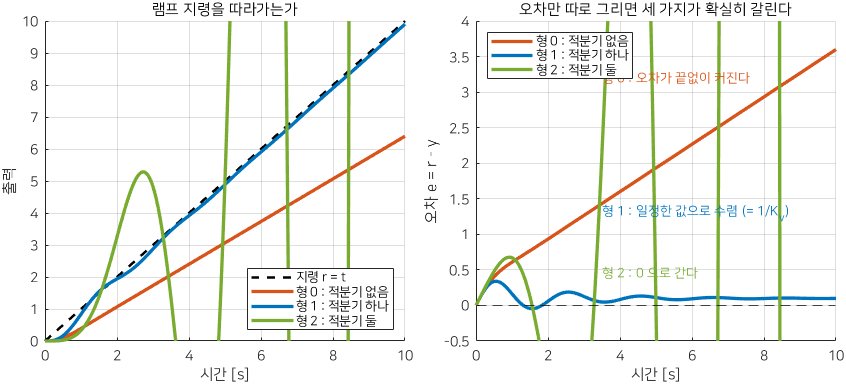

램프를 쫓는 모습과 그때의 오차

**그림 파일** `w11b_type_ramp.png` — `make_figures.m` 의 `fig_w11b_type_ramp` · 다시 만들려면 `make_figures('w11b_type_ramp')`

먼저 **손으로** 해 보십시오. 1분이면 됩니다.

제어기를 이득만 있는 것($C = K$)으로 두면 루프이득은 $L = KG$ 입니다. $G$ 에 $s$ 가 분모에 하나 있으니 **시스템 형은 1형**입니다. 1형의 램프 오차는 속도오차상수 $K_v$ 로 정해집니다.


$$K_v = \lim_{s \to 0} s L(s) = \lim_{s \to 0} s \cdot \frac{5K}{s(s+2)(s+20)} = \frac{5K}{2 \times 20} = \frac{K}{8}$$


램프 기울기가 $A$ 일 때 정상상태오차는 $e_{ss} = A/K_v$ 입니다. 여기서 $A = 0.5$ 이고 사양은 $0.04$ 이하이므로


$$\frac{0.5}{K_v} \le 0.04 \quad \Rightarrow \quad K_v \ge 12.5 \quad \Rightarrow \quad K \ge 100$$


**그래서 **$K = 100$** 입니다.** 아래에서 숫자로 확인합니다.

A_ramp = 0.5;

## 1-1. $K$ 를 훑어 손계산을 확인한다

$K$ 를 여섯 개 넣어 $K_v$ 와 램프 오차를 재 봅니다. $K_v$ 는 손계산대로 $K/8$ 이 나와야 합니다.

`dcgain(s*L)` 이 $\lim_{s \to 0} sL(s)$ 를 그대로 계산해 줍니다. 강의노트 2-1절에서 쓴 방법입니다.

Kv_list = [40 60 80 100 150 200]';
m = numel(Kv_list);
Kv_v = zeros(m,1); ess_v = zeros(m,1);
pm_v0 = zeros(m,1); gm_v0 = zeros(m,1); wc_v0 = zeros(m,1);

for k = 1:m
    Lk = NaN;
    % TODO : Lk = Kv_list(k)*G;  로 바꾸십시오
    if ~isa(Lk, 'tf'), break, end

    Kv_v(k)  = dcgain(s*Lk);
    ess_v(k) = A_ramp/Kv_v(k);
    [g, pm_v0(k), ~, wc_v0(k)] = margin(Lk);
    gm_v0(k) = 20*log10(g);
end

if all(Kv_v == 0)
    fprintf('  Lk 를 아직 안 만들었습니다.\n');
else
    table(Kv_list, Kv_v, Kv_list/8, ess_v, pm_v0, gm_v0, wc_v0, ...
        'VariableNames', {'K', 'Kv_실측', 'Kv_손계산', 'ess_rad', ...
                          'PM_deg', 'GM_dB', 'wc'})
end

## 1-2. $K = 100$ 의 여유를 읽는다

사양 1번은 $K = 100$ 으로 맞았습니다. 그런데 여유는 어떻습니까?

`margin` 하나로 네 개가 다 나옵니다. 강의노트 2-3절입니다.

K = 100;
L0 = K*G;

[gm0, pm0, ~, wc0] = margin(L0);

% 전압도 같이 재 둡니다. 램프를 그대로 주면 $t = 0$ 에서 속도가 갑자기
% $0$ 에서 $0.5$ 로 뛰어 전압이 필요 이상으로 커집니다. 그래서 강의노트 9절처럼
% **출발을 완만하게** 만든 램프를 씁니다. 1차 필터 $1/(\tau s + 1)$ 을 지령에
% 통과시킨 것과 같고, 식으로 쓰면 이렇습니다.
%
% $$\frac{A}{s^2} \cdot \frac{1}{\tau s + 1} \quad \Rightarrow \quad
%   r(t) = A\left(t - \tau\left(1 - e^{-t/\tau}\right)\right)$$
%
% - $t$ 가 커지면 $e^{-t/\tau} \to 0$ 이므로 기울기는 그대로 $A$ 다.
%   정상상태오차는 바뀌지 않는다
% - $t = 0$ 에서는 $r = 0$ 이고 $\dot{r} = 0$ 이다. 그래서 출발이 둥글다
% - $\tau = 0.2$ 초로 둔다. 이 값도 설계의 일부다 (강의노트 6절)
%
% 이 지령은 2절에서도 그대로 씁니다.

tau = 0.2;
t   = (0:1e-4:6)';
r   = A_ramp*(t - tau*(1 - exp(-t/tau)));
u0  = lsim(minreal(K/(1 + L0)), r, t);

fprintf('\n=== K = 100 일 때 ===\n');
fprintf('  Kv   = %.4f   (사양 12.5 이상)\n', dcgain(s*L0));
fprintf('  ess  = %.5f rad (사양 0.04 이하)\n', A_ramp/dcgain(s*L0));
fprintf('  PM   = %.4f deg (사양 45 이상)\n', pm0);
fprintf('  GM   = %.4f dB  (사양 8 이상)\n', 20*log10(gm0));
fprintf('  umax = %.4f V   (사양 12 이하)\n', max(abs(u0)));
fprintf('  wc   = %.4f rad/s\n', wc0);

## 1-3. 답할 것

- 사양 네 개 중 **몇 개가 합격**입니까? 어느 것이 떨어졌습니까?

- $K$ 를 더 **키우면** 떨어진 사양이 좋아집니까, 나빠집니까? 1-1절 표에서 $K = 150$, $200$ 줄을 보고 답하십시오

- $K$ 를 **줄이면** 어떻게 됩니까? 사양 1번은 어떻게 됩니까?

- 그러므로 $K$ 만으로는 끝낼 수 **없습니다.** 왜 그렇습니까? 한 문장으로 쓰십시오

- $K_v$ 실측과 손계산이 정확히 같습니까? 다르면 어디서 틀렸는지 찾으십시오

## 2. 기본 — Lead 로 위상을 끌어올린다

**강의노트 4절 ~ 4-3절과 8-3절을 보면 됩니다.**

$K = 100$ 은 **그대로 둡니다.** 사양 1번이 거기에 묶여 있기 때문입니다. 이득을 건드리지 않고 **위상만** 올리는 제어기가 Lead 입니다.

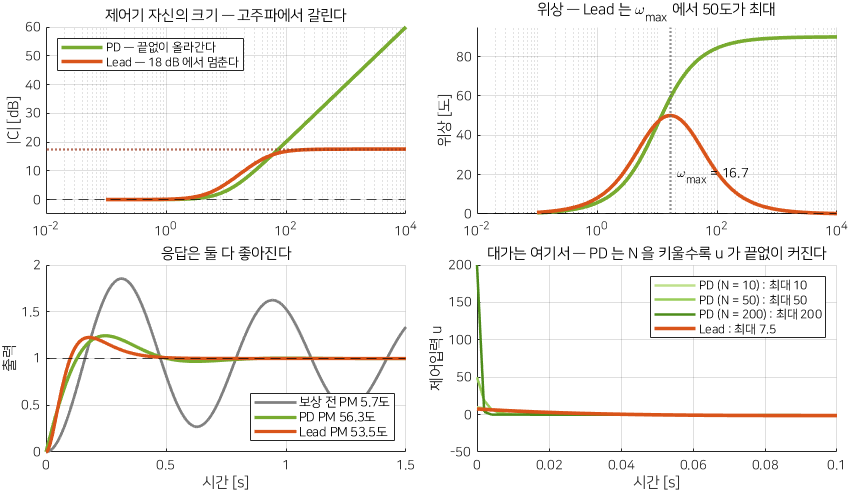

PD 와 Lead — 위상은 비슷하게 주고 고주파에서 갈린다

**그림 파일** `w11b_pd_vs_lead.png` — `make_figures.m` 의 `fig_w11b_pd_vs_lead` · 다시 만들려면 `make_figures('w11b_pd_vs_lead')`

Lead 는 이렇게 씁니다 (강의노트 4-1절).


$$C(s) = K \, \frac{1 + Ts}{1 + \alpha Ts}, \qquad 0 < \alpha < 1$$


설계에 쓰는 공식 세 개입니다. 전부 강의노트 4-1절에서 유도한 것입니다.

바꿀 수 있는 손잡이는 **두 개**입니다 — $\phi_{max}$ 와 $\omega_{max}$.

## 2-1. 부족한 각만큼만 올려 본다 — 실패하는 것을 먼저 본다

교과서의 첫 시도는 이렇습니다.

- 지금 PM 이 $9.5867^\circ$ 이고 사양이 $45^\circ$ 이므로 **부족한 각은** $45 - 9.5867 = 35.4133^\circ$

- 그 각을 **지금의 **$\omega_c$ 인 $4.7339$ rad/s 에 놓는다

손으로 먼저 하십시오.


$$\alpha = \frac{1 - \sin 35.4133^\circ}{1 + \sin 35.4133^\circ} = 0.26625, \qquad T = \frac{1}{4.7339\sqrt{0.26625}} = 0.40939$$


이대로 하면 PM 이 $45^\circ$ 가 될 것 같습니다. **되지 않습니다.** 아래에서 확인하십시오.

phi_need = 45 - pm0;

al1 = NaN;  T1 = NaN;
% TODO : 아래 두 줄을 공식대로 바꾸십시오
% al1 = (1 - sind(phi_need))/(1 + sind(phi_need));
% T1  = 1/(wc0*sqrt(al1));

if isnan(al1) || isnan(T1)
    fprintf('  al1 과 T1 을 아직 안 넣었습니다.\n');
else
    C1 = K*(1 + T1*s)/(1 + al1*T1*s);
    [g1, p1, ~, w1] = margin(C1*G);
    table(phi_need, al1, T1, -10*log10(al1), p1, 20*log10(g1), w1, ...
        'VariableNames', {'부족한_각_deg', 'alpha', 'T', '부스트_dB', ...
                          'PM_deg', 'GM_dB', 'wc'})
    fprintf('  목표는 PM 45 였는데 %.4f 가 나왔습니다.\n', p1);
    fprintf('  wc 가 %.4f 에서 %.4f 로 **옮겨갔습니다.**\n', wc0, w1);
end

## 2-2. 왜 실패했는가, 그리고 어떻게 고치는가

이유는 하나입니다. **Lead 는 위상만 올리는 것이 아니라 크기도 올립니다.**

- $\omega_{max}$ 에서 크기를 $-10\log_{10}\alpha$ dB 만큼 올렸다

- 크기 곡선이 위로 올라가면 $0$ dB 를 지나는 자리가 **오른쪽으로** 옮겨간다

- 옮겨간 그 자리에서는 플랜트 위상이 더 많이 떨어져 있다

- 그래서 $35.41^\circ$ 를 올려 주고도 PM 은 $35.41^\circ$ 만큼 안 오른다

강의노트 4-2절의 다섯 단계는 이것을 **여유를 더 주어** 해결합니다. 여기서는 $\phi_{max}$ 를 넉넉히 $55^\circ$ 로 고정하고 $\omega_{max}$** 를 옮겨 가며** 재 봅니다. 손잡이 하나만 움직이는 것입니다.

$\phi_{max} = 55^\circ$ 이면 손으로 이렇게 됩니다.


$$\alpha = \frac{1 - \sin 55^\circ}{1 + \sin 55^\circ} = 0.099413, \qquad -10\log_{10}\alpha = 10.0256 \ \mathrm{dB}$$


그리고 고주파 이득은 $C(\infty) = K/\alpha = 1005.9$ 로 $\omega_{max}$** 와 무관하게 고정**됩니다. 강의노트 8-6절에서 문제가 된 그 숫자입니다.

네 사양을 다 재려면 전압도 재야 합니다. 지령 `r` 과 시간 `t` 는 **1-2절에서 만든 것을 그대로** 씁니다.

phi_fix = 55;
al = (1 - sind(phi_fix))/(1 + sind(phi_fix));

wm_list = [6 8 9 11 13 16 18]';
n = numel(wm_list);
pm_v = zeros(n,1); gm_v = zeros(n,1); wc_v = zeros(n,1);
um_v = zeros(n,1); es_v = zeros(n,1);

for k = 1:n
    Ck = NaN;
    % TODO : 아래 두 줄의 주석을 푸십시오
    % Tk = 1/(wm_list(k)*sqrt(al));
    % Ck = K*(1 + Tk*s)/(1 + al*Tk*s);
    if ~isa(Ck, 'tf'), break, end

    [g, pm_v(k), ~, wc_v(k)] = margin(Ck*G);
    gm_v(k) = 20*log10(g);

    u = lsim(minreal(Ck/(1 + Ck*G)), r, t);
    um_v(k) = max(abs(u));

    % 정상상태오차는 Kv 로 잰다 (2-6절에 이유가 있다)
    es_v(k) = A_ramp/dcgain(s*Ck*G);
end

if all(pm_v == 0)
    fprintf('  제어기 Ck 를 아직 안 만들었습니다.\n');
else
    fprintf('\n  alpha = %.6f, 부스트 = %.4f dB, C(inf) = K/alpha = %.2f\n', ...
        al, -10*log10(al), K/al);
    table(wm_list, pm_v, gm_v, wc_v, um_v, es_v, ...
        'VariableNames', {'wmax', 'PM_deg', 'GM_dB', 'wc', 'umax_V', 'ess_rad'})
end

## 2-3. 합격선을 긋는다

표를 눈으로 보고 고르지 마십시오. **네 조건을 논리식으로** 써서 MATLAB 이 고르게 합니다. 11A주차 과제에서 하던 것과 같은 방식입니다.

if any(pm_v ~= 0)
    ok = NaN;
    % TODO : ok = (pm_v >= 45) & (gm_v >= 8) & (um_v <= 12) & (es_v <= 0.04);
    %        로 바꾸십시오

    if ~islogical(ok)
        fprintf('  ok 를 아직 안 채웠습니다.\n');
    elseif any(ok)
        fprintf('\n  합격한 wmax : ');
        fprintf('%g ', wm_list(ok));  fprintf('\n');
    else
        fprintf('\n  이 일곱 개 중에는 합격이 없습니다.\n');
    end
end

## 2-4. 촘촘히 훑어 합격 구간의 양쪽 끝을 찾는다

합격하는 값이 **하나가 아니라 구간**입니다. 그 구간의 양쪽 끝이 어느 사양에 막혀 있는지가 설계자가 알아야 하는 것입니다.

여기서는 PM 과 GM 만 촘촘히 잽니다. 전압은 2-2절 표에서 보셨듯이 이 범위 전체에서 $11$ V 를 넘지 않고, 오차는 $K$ 로만 정해지므로 $\omega_{max}$ 를 어떻게 놓아도 $0.04$ 에서 꼼짝하지 않습니다.

**코드는 다 되어 있습니다.** 출력을 보고 2-5절에 답하십시오.

wv = 6:0.1:20;
q = numel(wv);
pm_s = zeros(q,1); gm_s = zeros(q,1); wc_s = zeros(q,1);

for k = 1:q
    Tk = 1/(wv(k)*sqrt(al));
    Ck = K*(1 + Tk*s)/(1 + al*Tk*s);
    [g, pm_s(k), ~, wc_s(k)] = margin(Ck*G);
    gm_s(k) = 20*log10(g);
end

pass = (pm_s >= 45) & (gm_s >= 8);

i_lo = find(pass, 1);
i_hi = find(pass, 1, 'last');

fprintf('\n=== 합격 구간 ===\n');
if ~isempty(i_lo)
    fprintf('  wmax = %.1f 부터 %.1f 까지\n', wv(i_lo), wv(i_hi));
end

[pm_best, i_best] = max(pm_s);
fprintf('  PM 이 가장 큰 곳 : wmax = %.1f 에서 %.4f 도\n', wv(i_best), pm_best);
if i_lo > 1
    fprintf('  왼쪽 끝 바로 밖 (wmax = %.1f) : PM %.4f 도\n', ...
        wv(i_lo-1), pm_s(i_lo-1));
end
if i_hi < q
    fprintf('  오른쪽 끝 바로 밖 (wmax = %.1f) : PM %.4f 도\n', ...
        wv(i_hi+1), pm_s(i_hi+1));
end
fprintf('  이 범위에서 GM 은 최소 %.4f dB 입니다 (사양 8)\n', min(gm_s));

## 2-5. 답할 것

- 합격 구간의 **왼쪽 끝**은 어느 사양에 막혀 있습니까? **오른쪽 끝**은? (두 끝이 **같은 사양**에 막혀 있습니다. 그것을 확인하십시오)

- PM 을 $\omega_{max}$ 에 대해 그려 보면 **봉우리** 모양입니다. $\omega_{max}$ 를 너무 낮게 두면 PM 이 떨어지는 이유는 무엇입니까? 너무 높게 두면 떨어지는 이유는? (힌트 — Lead 가 주는 위상은 $\omega_{max}$ 에서 최대이고, $\omega_c$ 는 $\omega_{max}$ 가 커지면 왼쪽으로 옮겨갑니다. 2-2절 표의 `wc` 열을 보십시오)

- 사양 네 개 중 **실제로 설계를 묶은 것은 몇 개**입니까? 나머지 사양은 없어도 되는 것입니까?

- 합격 구간 안에서 하나를 고르십시오. **왜 그 값인지** 한 문장으로 쓰십시오 (PM 이 가장 큰 자리를 고르는 것도 답이 됩니다. 이유를 쓰면 됩니다)

## 2-6. 고른 값으로 최종 확인

고른 $\omega_{max}$ 를 넣어 네 사양을 한 번에 재고 그림을 봅니다.

wm_pick = 11;      % <-- 2-5 에서 고른 값으로 바꾸십시오

T_pick = 1/(wm_pick*sqrt(al));
C_fin  = K*(1 + T_pick*s)/(1 + al*T_pick*s);
L_fin  = minreal(C_fin*G);
T_cl   = minreal(L_fin/(1 + L_fin));

[gmf, pmf, ~, wcf] = margin(L_fin);
u_fin = lsim(minreal(C_fin/(1 + C_fin*G)), r, t);
y_fin = lsim(T_cl, r, t);

fprintf('\n=== 고른 설계 (wmax = %g) ===\n', wm_pick);
fprintf('  alpha %.6f, T %.6f, 영점 %.4f, 극점 %.4f\n', ...
    al, T_pick, 1/T_pick, 1/(al*T_pick));
C_fin

% 사양 1번은 **정상상태** 값이므로 $K_v$ 로 재는 것이 맞습니다. Lead 의 직류이득은
% $1$ 이므로 ($s = 0$ 에서 $(1+Ts)/(1+\alpha Ts) = 1$) $K_v$ 는 1절의 $12.5$ 에서
% 꼼짝하지 않습니다. 6초 시늉의 꼬리를 쓰면 과도응답이 완전히 안 죽어서
% $10^{-12}$ 쯤 더 크게 나옵니다. 그래서 둘을 따로 보여 줍니다.

ess_fin = A_ramp/dcgain(s*L_fin);

spec_name = {'1_ramp_ess_rad'; '2_PM_deg'; '3_GM_dB'; '4_umax_V'};
got  = [ess_fin; pmf; 20*log10(gmf); max(abs(u_fin))];
need = [0.04; 45; 8; 12];
pass4 = [got(1) <= need(1); got(2) >= need(2); got(3) >= need(3); got(4) <= need(4)];
disp(table(got, need, pass4, 'RowNames', spec_name, ...
    'VariableNames', {'측정값', '사양', '합격'}))
fprintf('  Kv = %.4f (1절의 12.5 와 같다. Lead 는 직류이득을 안 바꾼다)\n', ...
    dcgain(s*L_fin));
fprintf('  6초 시늉의 꼬리 = %.12f rad (위 값과 %.1e 차이. 과도응답 잔류)\n', ...
    r(end) - y_fin(end), (r(end) - y_fin(end)) - ess_fin);

tiledlayout(1,3)
nexttile
margin(L_fin); grid on; title('보드 선도와 여유')
nexttile
plot(t, r, 'k--', 'LineWidth', 1.4); hold on
plot(t, y_fin, 'LineWidth', 2);
xlabel('시간 [s]'); ylabel('위치 [rad]');
legend('지령', '출력', 'Location', 'southeast'); grid on
title('램프 추종');
nexttile
plot(t, u_fin, 'LineWidth', 2); hold on
yline(12, 'r--'); yline(-12, 'r--');
xlabel('시간 [s]'); ylabel('전압 [V]'); grid on
title('제어입력과 한계');

## 2-7. 그림에서 확인할 것

- 가운데 그림에서 지령과 출력이 **평행**합니까? 벌어진 간격이 $e_{ss}$ 입니다. 그 간격을 눈으로 재어 $0.04$ rad 와 맞는지 보십시오

- 오른쪽 그림에서 전압의 **봉우리가 언제** 생깁니까? 왜 거기입니까? ($\tau = 0.2$ 초와 비교해 보십시오)

- 1-2절에서 $K$ 만 있을 때의 전압은 $10.36$ V 였습니다. Lead 를 넣었더니 $8.54$ V 로 **줄었습니다.** 제어기를 더 넣었는데 전압이 왜 줄었습니까? (힌트 — $K$ 만 있을 때 PM 이 $9.59^\circ$ 였습니다. 그때 오차는 어떻게 움직입니까?)

- 왼쪽 보드 선도에서 Lead 가 넣은 영점과 극점이 보입니까? 크기 곡선의 기울기가 꺾이는 두 자리를 찾으십시오

- 강의노트 8-6절은 "앱은 $u$ 를 보여 주지 않는다" 고 했습니다. 여기서 $u$ 를 안 쟀다면 무엇을 못 봤을지 한 문장으로 쓰십시오

## 3. 도전 (선택) — 이 설계가 견디는 수송지연의 한계

**강의노트 8-5절을 그대로 보면 됩니다.** 가산점 10점입니다.

실제 장치에는 계산 시간과 통신 지연이 있습니다. 지연은 **크기를 전혀 건드리지 않고 위상만** 깎습니다.

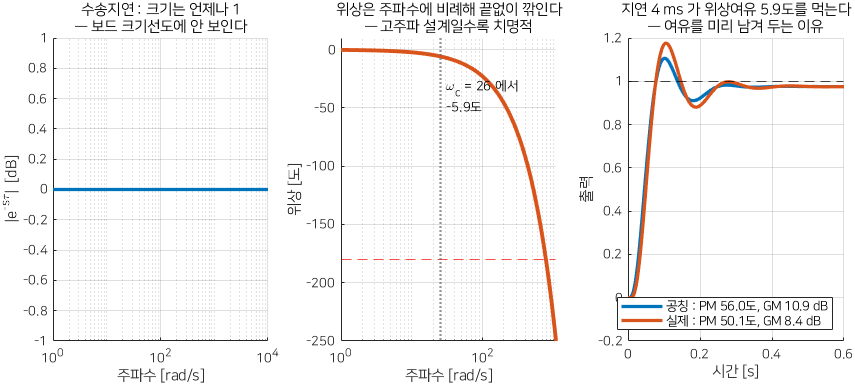

수송지연은 크기를 안 건드리고 위상만 깎는다

**그림 파일** `w11b_delay.png` — `make_figures.m` 의 `fig_w11b_delay` · 다시 만들려면 `make_figures('w11b_delay')`

지연 $T_d$ 의 주파수응답은 이렇습니다.


$$s = j\omega \quad \Rightarrow \quad e^{-sT_d} = e^{-j\omega T_d} \quad \Rightarrow \quad |e^{-j\omega T_d}| = 1, \qquad \angle e^{-j\omega T_d} = -\omega T_d \ \mathrm{[rad]}$$


크기가 항상 $1$ 이므로 $\omega_c$** 는 전혀 움직이지 않습니다.** 그래서 깎이는 위상여유를 손으로 바로 계산할 수 있습니다.


$$\Delta \mathrm{PM} = \omega_c T_d \cdot \frac{180}{\pi} \ \mathrm{[deg]}$$


2-6절 설계의 PM 이 $48.5756^\circ$, $\omega_c$ 가 $7.1240$ rad/s 였습니다. 사양은 $45^\circ$ 이므로 쓸 수 있는 여분은 $3.5756^\circ$ 뿐입니다. 먼저 **손으로** 한계를 구하십시오.


$$T_{d,max} = \frac{\Delta \mathrm{PM} \cdot \pi / 180}{\omega_c} = \frac{3.5756 \times \pi / 180}{7.1240} = ? \ \mathrm{[s]}$$


Td_max = NaN;
% TODO : Td_max = (pmf - 45)*pi/180/wcf;  로 바꾸십시오

if isnan(Td_max)
    fprintf('  Td_max 를 아직 안 구했습니다.\n');
else
    fprintf('\n  손으로 구한 한계 : Td_max = %.6f s (%.3f ms)\n', ...
        Td_max, Td_max*1000);
end

## 3-1. `pade` 로 검산한다

지연은 유리함수가 아니므로 `margin` 에 바로 넣을 수 없습니다. `pade` 가 유리함수로 근사해 줍니다. 강의노트 8-5절에서 쓴 방법입니다.

- **원리** — $e^{-sT_d}$ 를 같은 차수의 분수로 근사한다 (크기는 $1$ 에 가깝게, 위상은 $-\omega T_d$ 에 가깝게)

- **입력** — `pade(Td, N)` : 지연 시간과 차수

- **출력** — `[num, den]` 두 벡터. `tf(num, den)` 으로 전달함수를 만든다

- **주의** — 차수 $N$ 이 낮으면 $\omega T_d$ 가 클 때 위상이 어긋난다. 여기서는 $3$ 차로 충분하다

- **예제** — 아래

if ~isnan(Td_max)
    td_try = [0, Td_max/2, Td_max, Td_max*1.5, 0.02]';
    pm_d = zeros(5,1); gm_d = zeros(5,1); wc_d = zeros(5,1);

    for k = 1:5
        if td_try(k) == 0
            Ld = L_fin;
        else
            [nd, dd] = pade(td_try(k), 3);
            Ld = L_fin*tf(nd, dd);
        end
        [g, pm_d(k), ~, wc_d(k)] = margin(Ld);
        gm_d(k) = 20*log10(g);
    end

    table(td_try*1000, pm_d, gm_d, wc_d, pmf - wc_d.*td_try*180/pi, ...
        'VariableNames', {'Td_ms', 'PM_실측_deg', 'GM_dB', 'wc', '손계산_PM_deg'})
end

## 3-2. 답할 것

- $T_d = T_{d,max}$ 줄에서 PM 이 정확히 $45^\circ$ 가 나왔습니까? 손계산 열과 실측 열이 맞습니까?

- $\omega_c$ 열은 지연을 넣어도 **변하지 않습니다.** 왜 그렇습니까? 위의 유도에서 어느 줄이 그 이유입니까?

- $T_d = 20$ ms 면 PM 이 얼마입니까? 사양을 만족합니까? 만족하지 못하면 **무엇을 고쳐야** 합니까? (2-5절에서 고른 값을 바꾸는 것도 방법입니다. 어느 쪽으로 바꿔야 할지 2-4절 출력을 보고 답하십시오)

- $\omega_c$ 가 큰 설계와 작은 설계 중 어느 쪽이 지연에 **약합니까?** 공식 $\Delta \mathrm{PM} = \omega_c T_d$ 를 보고 답하십시오

- 2-5절에서 "PM 이 가장 큰 자리" 를 고르는 것이 왜 좋은 선택이었는지 **이제** 말할 수 있습니까?

## 4. 제출

- 이 파일의 `TODO` 를 모두 채운 `.m` 파일

- 1-3 · 2-5 · 2-7 · 3-2 의 답 (한글 텍스트, 각 한두 문장)

- 2-6 의 그림 세 장

**채점 기준**

숫자만 맞고 **이유가 없으면 절반**입니다. 이 과제는 "왜 그 값인가" 를 묻는 과제입니다.